load('exp/exp_diff_h/exp10_w_BM.mat');


## Figure 1: prevented loss and the discounted profit of the insurer

fprintf('lowest premium with full mitigation: %.3f\n', premium_list(find(Miti_retention_list(:, 2) > 20 - 0.001, 1, 'first')));

lowest premium with full mitigation: 4.260



transition1_counter = find(BM_retention_list(:, 1) == 0, 1, "last");
transition1 = premium_list(transition1_counter);
transition2_counter = find(BM_retention_list(:, 1) < 20, 1, "last");
transition2 = premium_list(transition2_counter);
profit_list = detail_list(:, 2) + detail_list(:, 3) - detail_list(:, 5);

fprintf('transition 1: %.3f\n', transition1);

transition 1: 4.230


fprintf('mitigation at transition 1: %.3f\n', Miti_retention_list(transition1_counter, 2));

mitigation at transition 1: 19.893


fprintf('profit at transition 1: %.3f\n', profit_list(transition1_counter));

profit at transition 1: -0.282


fprintf('loss prevention at transition 1: %.3f\n', detail_list(transition1_counter, 6));

loss prevention at transition 1: 16.759


fprintf('transition 2: %.3f\n', transition2);

transition 2: 4.255


fprintf('mitigation at transition 2: %.3f\n', Miti_retention_list(transition2_counter, 2));

mitigation at transition 2: 19.914


fprintf('profit at transition 2: %.3f\n', profit_list(transition2_counter));

profit at transition 2: -0.057


fprintf('loss prevention at transition 2: %.3f\n', detail_list(transition2_counter, 6));

loss prevention at transition 2: 16.770


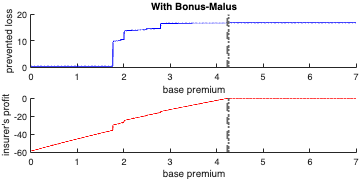


line_width = 1.2;

figure('Position', [100, 100, 400, 200]);
[ha, pos] = tight_subplot(2, 1, [0.17, 0.15], [0.155, 0.08], [0.085, 0.01]);

% upper panel
axes(ha(1));
hold on;
plot(premium_list, detail_list(:, 6), ...
    'LineWidth', line_width, 'Color', 'blue');
line([transition1, transition1], get(gca, 'YLim'), 'Color', [0.4, 0.4, 0.4], ...
    'LineStyle', '--', 'LineWidth', 2);
line([transition2, transition2], get(gca, 'YLim'), 'Color', [0.4, 0.4, 0.4], ...
    'LineStyle', ':', 'LineWidth', 2);

xlabel('base premium');
ylabel('prevented loss');

title("With Bonus-Malus");

% lower panel
axes(ha(2));
hold on;
plot(premium_list, profit_list, ...
    'LineWidth', line_width, 'Color', 'red');
line([transition1, transition1], get(gca, 'YLim'), 'Color', [0.4, 0.4, 0.4], ...
    'LineStyle', '--', 'LineWidth', 2);
line([transition2, transition2], get(gca, 'YLim'), 'Color', [0.4, 0.4, 0.4], ...
    'LineStyle', ':', 'LineWidth', 2);

xlabel('base premium');
ylabel('insurer''s profit');

## Figure 2: retention of insurance customers and adoption of self-mitigation

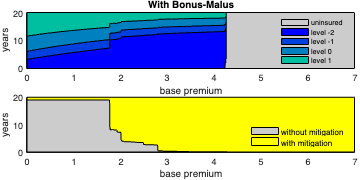

figure('Position', [100, 100, 400, 200]);
[ha, pos] = tight_subplot(2, 1, [0.16, 0.15], [0.155, 0.07], [0.075, 0.015]);

% upper panel
axes(ha(1));
BM_num = size(BM_retention_list, 2) - 1;
BM_legend = cell(BM_num + 1, 1);
BM_legend{1} = 'uninsured';
for BM_id = 1:BM_num
    BM_legend{BM_id + 1} = sprintf('level %d', ...
        BM_id - BM.init);
end

colorlist = [[0.8, 0.8, 0.8]; winter];
colormap_rows = [1, round(linspace(2, 257, BM_num + 1))];

BM_list = [zeros(size(BM_retention_list, 1), 1), ...
    cumsum(BM_retention_list, 2)];
BM_list = min(BM_list, params.horizon);


hold on;
for BM_id = 1:BM_num + 1
    fill([premium_list; flipud(premium_list)], ...
        [BM_list(:, BM_id); flipud(BM_list(:, BM_id + 1))], ...
        colorlist(colormap_rows(BM_id), :), 'LineWidth', 0.5);
end
legend(BM_legend, 'Location', 'southeast', 'Orientation',"vertical", 'FontSize', 8, 'Color', 'none');
legend boxoff
xlabel('base premium');
ylabel('years')

title('With Bonus-Malus')

% lower panel
axes(ha(2));
miti_legend = {'without mitigation', 'with mitigation'};

colorlist = [0.8, 0.8, 0.8; 1, 1, 0];

Miti_list = [zeros(size(Miti_retention_list, 1), 1), ...
    cumsum(Miti_retention_list, 2)];
Miti_list = min(Miti_list, params.horizon);

hold on;
for Miti_id = 1:length(Miti.cost)
    fill([premium_list; flipud(premium_list)], ...
        [Miti_list(:, Miti_id); flipud(Miti_list(:, Miti_id + 1))], ...
        colorlist(Miti_id, :), 'LineWidth', 0.5);
end
legend(miti_legend, 'Location', 'southeast', "Orientation","vertical", 'Color', 'none');
legend boxoff
xlabel('base premium');
ylabel('years')